# Comparison of solution times

The current version is updated in ultimo January, 2023.

*Clean workspace, layout settings:*

clear;
clc;
close all;
base.layout();

This workbook solvs the model in various way and with varying numerical precision, to compare solution times. Specifically:

- We compare three solution types: (1) Time-dependent, finite horizon, (2) time-dependent, infinite horizon, and (3) time-independent, infinite horizon (steady state approximation).

- We compare solution times across three grid-levels: 10, 100, 1000.

- For each solution, we also report the number of iterations required for each type and the largst numerical error.

## 1. Settings

Load calibration from the Argentina case:

load('ArgentinaParameters.mat','out');
load('ArgentinaParametersIH.mat','IH_par');
load('ArgentinaTargets.mat','target');

Save all timings in this struct:

time = struct();

Define labor supply function grid (the same for all methods):

- approx.n: Number of gridpoints for $\tau_t$ in approximation of labor function.

- approx.nn: Number of gridpoints for $\tau_{t+1}$ in approximation of labor function.

- approx.s, approx.ss: Shape parameters used in nonlinear grid functions.

approx = struct('n',250,'nn',250,'s',0.7,'ss',1.2);

Define numerical settings (add length of nu grid later):

- np.tol_diff: Maximum difference between two iterations when identifying a fixed point.

- np.tol_solver: Maximum tolerance for numerical solvers.

- np.max_iter: Upper bound on number of iterations applied in various algorithms.

- np.n_h: Number of gridpoints in the grid of $h$

- np:n_test: Size of grid of taxes to test if the algorithm has converged.

np = struct('tol_diff',1e-5,'tol_solver',1e-7,'max_iter',50,'n_h',150,'n_test',100);

From this, start by defining an approximation of the labor function for the time-dependent infinite horizon case and the steady state approximation case (the two are different because the calibration yields different parameter values):

tic;
hfunc = IH.h_EE_approximation(out.par,approx); 


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

time.hfunc = toc;
tic; 
hfuncIH = IH.h_EE_approximation(IH_par,approx);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

time.hfuncIH = toc;

For the time-dependent functions, there is a single way to solve the model (with the "true") structure of $\nu$. For the steady state approximation, however, we can solve the model on a grid of $\nu$ and interpolate for values between. We solve for various numbers of grids on $\nu$ here:

ngrids = [10,20,30]; % number of gridpoints to solve steady state approximation over
[grids, time.ss, sols, nps] = deal(cell(length(ngrids),1));
for i =1:length(ngrids)
    grids{i} = struct('h', linspace(hfuncIH(1,0), hfuncIH(0,1),np.n_h),...
                      'test', linspace(0.01, 0.99, np.n_test),...
                      'nu', linspace(min(IH_par.nu_v), max(IH_par.nu_v), ngrids(i)));
    nps{i} = np;
    nps{i}.n_nu = ngrids(i);
end

The time-dependent function in infinite horizon relies on the same grid struct as input, but only requires that we solve for one value of $\nu$ - the terminal value in the data:

np_td = np;
np_td.n_nu = 1;
grids_td = grids{1}; grids_td.nu = out.par.nu_v(end); %

## 2. Finite Horizon, EGM solution:

Time the solution for the EGM, finite horizon solution approach. 

%parpool; % get the parallel pool ready before timing the code
tic
SolveF.identify_policy(out.par);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

time.FH_TD = toc;

## 3. Infinite Horizon, time dependent solution:

Time the solution time for the EGM, finite horizon solution approach:

TD_IH = struct();
tic
[TD_IH.sample, TD_IH.dif, TD_IH.maxdiff, TD_IH.iter] = IH.identifyPolicy(out.par, np_td, grids_td, hfunc, nan);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

time.TD_IH = toc;

## 4. Steady state approximation

Identify solution for each $\nu$ grid:

for i=1:length(ngrids)
    sols{i} = struct();
    tic
    [sols{i}.sample,sols{i}.dif,sols{i}.maxdiff, sols{i}.iter, sols{i}.tau,sols{i}.tau_m, sols{i}.h] = IH.GradientFree_Policy(IH_par, nps{i}, grids{i}, hfuncIH, nan);
    time.ss{i} = toc;
end

Print the policies for two very close values of $\nu$ around the problem:

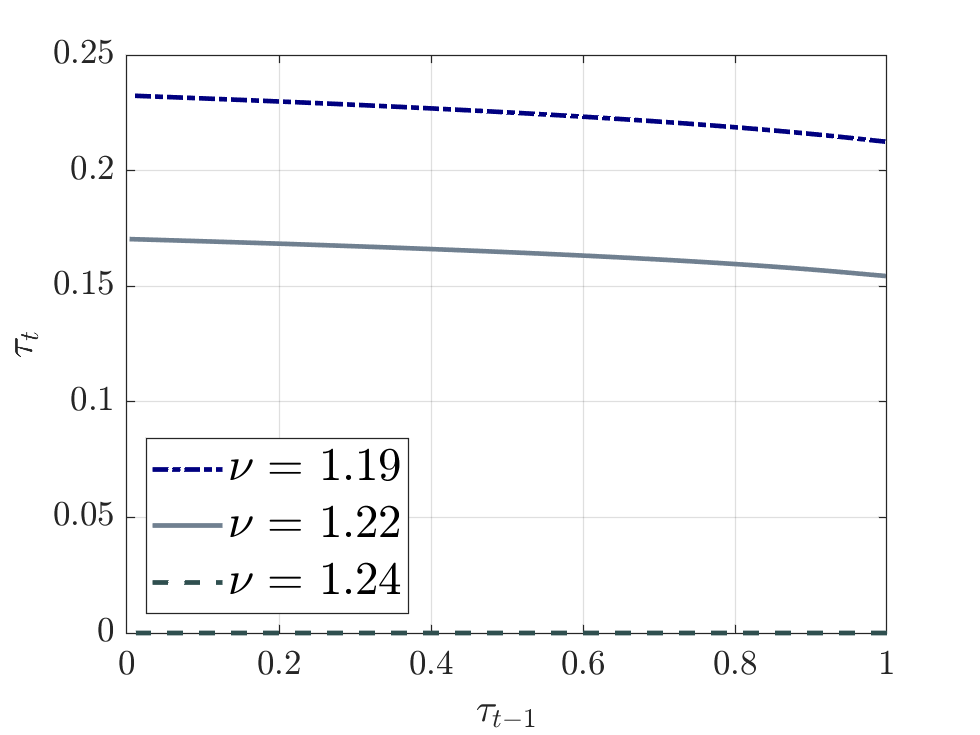

psettings = figs.def_psettings(struct());
print = 1; % If 1 print to pdf, if 0 don't.
prefix = 'convergence';
figs.SSpolicies(psettings, sols{3}.tau, sols{3}.tau_m, 11, grids{3}, print, prefix);